# **AGRUPAMIENTO CON UNA RED SOM**

Este programa realiza un agrupamiento de datos con una red Selforganizing Map (SOM). Es un proceso de aprendizaje no supervisado donde los datos se agrupan en clases desconocidas a priori. Únicamente se sabe el número de clases en el que hay que agrupar esos datos, información que debe ser fijada por el usuario.

En este programa se realiza un **agrupamiento** con una parte de los datos con el objetivo de **entrenar** la red, que posteriormente **clasificará** el resto de los datos en cada una de las clases definidas en el proceso anterior. Esta opción es la más habitual en los problemas de agrupamiento y, en general, en los problemas de clasificación, donde hay un entrenamiento supervisado. Por ello se proporcionarán dos resultados: el agrupamiento obtenido con los datos de entrenamiento y la clasificación de los datos de validación proporcionada por la red ya entrenada.

En los problemas de agrupamiento hay otra opción: utilizar todos los datos disponible para entrenamiento y no realizar una clasificación posterior. El objtivo es **agrupar** un conjunto de datos en clases con el objetivo de obener información sobre esos datos y sus posibles relaciones. Si se opta por esta opción, en este programa, bastará con tomar todos los datos disponibles tanto para el conjunto de entrenamiento como para el de validación. En este caso, el programa proporcionará dos agrupamientos idénticos.

En este programa se van a agrupar los PIBs de todas las provincias españolas y portuguesas durante 20 años. Por tanto, cada provincia viene definida por un vector de 20 componentes. Hay un todal de 84 provincias: 59 españolas y 25 portuguesas. Las españolas van de la 1 a la 59 y las portuguesas de la 60 a la 84.

El objetivo del programa es agrupar todas las provincias en un número determinado de clases en función de la evolución de sus respectivos PIBs a lo largo de esos 20 años.

En primer lugar se cierran todas las ventana abiertas y se limpian todas las varibles.

clear all
close all

## **CARGA DE LOS DATOS**

Los datos están organizados por filas en una tabla: cada fila se corresponde con una provincia y las columnas definen los años. La primera columna corresponde al nombre de la provinicia.

[datos,provincias]=xlsread('PPSyVAB.xlsx','VABpc','A2:U85');
 

Dado que la instrucción *'train*' para entrena el SOM exije que los datos de entrada se le presenten en el formato **(número de variables) x (número de muestras),** habrá que organizar todos los valores de PIB de la misma forma: **(número de años) x (número de provincias)**. El nombre de las provincias, primera columna de la tabla, se organizan  en el mismo formato, **1 x (número de provincias)**, para homogeniezar la información.

datos=datos';
provincias=provincias';

## DEFINICIÓN DE LA RED SOM

Se puede elegir la opción de agrupar todos los datos para analizar las relaciones dentre esos datos sin realizar clasificacines posteriores. En este caso  se entrena con todos los datos disponible y se vuelven a clasificar posteriormente para analizar los resultados.

En caso contrario se dividirán los datos entre entrenamiento y clasificación.

En este ejemplo se van a ultizar para el entrenamieto los datos de España y para clasificación los de Portugal. Si quisieramos clasificarlos independientemente de su nacionalidad habría que barajarlos primero:

indiceReor=randperm(size(datos,2));

datos=datos(indiceReor,:);

Índices para seleccionar los datos para el entrenamiento: dato inicial y dato final.

datosEntIni=1;
datosEntFin=59;

Índices para seleccionar los datos para la clasificación: dato inicial y dato final.

datosClasIni=60;
datosClasFin=84;

Definición del tamaño de la red: *tamredy*tamred*. El resultado de este producto define el **número de clase**s.

tamredx=4;
tamredy=3;

**SELECCIÓN DE LOS DATOS DE ENTRENAMIENTO Y VALIDACIÓN**

datosEnt=datos(:,datosEntIni:datosEntFin);
datosClas=datos(:,datosClasIni:datosClasFin);

**CREACIÓN DE LA RED SOM**

redsom=selforgmap([tamredx,tamredy]);

**ENTRENAMIENTO DE LA RED ESOM.**

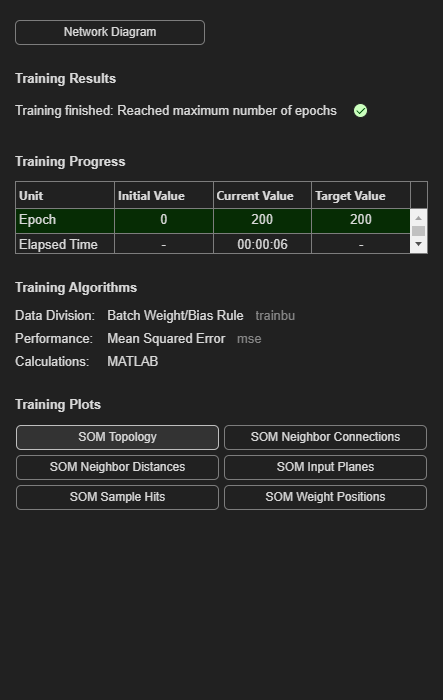

redsom=train(redsom,datosEnt);

**CLASIFICACIÓN DE LOS DATOS DE ENTRENAMIENTO Y CLASIFICACIÓN**

agrupClas=redsom(datosEnt);
agrupClas1=redsom(datosClas);

## CREACIÓN DE LA TABLA DONDE SE ASIGNAN PROVINCIAS A CLASES

Se proporcionan dos clasificiaciones: una con los datos de **entrenamiento** (agrupamiento), con el objeto de obtener información referente a las clases, y otra con los datos reservados para **clasificación**. 

En el caso de que se optara por **agrupar** todos los datos sin reservar ninguno para una posterior clasificación (solo interesa obtener información sobre los datos disponibles) se obtendarán dos agrupamientos con idénticos resultados.

El resultado de cada agrupamiento se guardará en una tabla (*tablaEnt* para el entrenamiento y *tablaClas* para la clasificación) que tendrá tantas filas como clases (*tamrex*tamredy*) y tantas columnas como elementos hay en la clase de mayor tamaño.

Definición de dos vectores de índices, que tienen en cada componente la posición de cada clase en la que hay que incluir una provincia.

indice(1:tamredx*tamredy)=ones;
indice1(1:tamredx*tamredy)=ones;

Agrupamiento de los datos utilizados para entrenamiento. Los agrupamientos se representan en una tabla donde aparecen las provincias de cada clase. También se obtiene la matriz *clasifEnt*, donde se asocia cada provincia a una clase, pero no se representa como resultado, aunque se puede consultar en el "*Workspace*".

for i=datosEntIni:datosEntFin 
    clase(i-datosEntIni+1)=find(agrupClas(:,i-datosEntIni+1));
    j=clase(i-datosEntIni+1);
    k=indice(j);
    ProvinciaE(j,k)=provincias(i);
    indice(j)=indice(j)+1;
end
clasifEnt(:,1)=provincias(datosEntIni:datosEntFin);
clasifEnt(:,2)=num2cell(clase(:));
tablaEnt=cell2table(ProvinciaE)

tablaEnt = 12×9 table
       ProvinciaE1           ProvinciaE2              ProvinciaE3          ProvinciaE4           ProvinciaE5                ProvinciaE6           ProvinciaE7      ProvinciaE8     ProvinciaE9 
    _________________    ____________________    _____________________    ______________    ______________________    _______________________    _____________    _____________    ____________

    {'Guadalajara'  }    {'Alicante/Alacant'}    {'Almería'          }    {'Ceuta'     }    {'Melilla'           }    {'Gran Canaria'       }    {0×0 double }    {0×0 double }    {0×0 double}
    {'Fuerteventura'}    {'Lanzarote'       }    {0×0 double         }    {0×0 double  }    {0×

Agrupamiento de los datos utilizados para clasificación. Los agrupamientos se representan en una tabla donde aparecen las provincias de cada clase. También se obtiene la matriz *clasifClas*, donde se asocia cada provincia a una clase, pero no se representa como resultado, aunque se puede consultar en el "*Workspace*".

La obtención del índice que coresponde a cada clase puede hacerse también de un golpe con la insturcción "*vec2ind*" en lugar de calcular columna a columna con la instrucción "*find*".

[clase1,filas]=vec2ind(agrupClas1);
for ii=datosClasIni:datosClasFin
    jj=clase1(ii-datosClasIni+1);
    kk=indice1(jj);
    ProvinciaC(jj,kk)=provincias(ii);
    indice1(jj)=indice1(jj)+1;
end
clasifClas(:,1)=provincias(datosClasIni:datosClasFin);
clasifClas(:,2)=num2cell(clase1(:));
tablaClas=cell2table(ProvinciaC)

tablaClas = 11×22 table
              ProvinciaC1               ProvinciaC2     ProvinciaC3               ProvinciaC4                ProvinciaC5         ProvinciaC6        ProvinciaC7             ProvinciaC8             ProvinciaC9         ProvinciaC10            ProvinciaC11             ProvinciaC12            ProvinciaC13         ProvinciaC14       ProvinciaC15             ProvinciaC16                ProvinciaC17          ProvinciaC18          ProvinciaC19           ProvinciaC20                   ProvinciaC21                           ProvinciaC22            
    ________________________________    <